# Problemas de valor inicial

## Sistema de dos ecuaciones lineales de primer orden

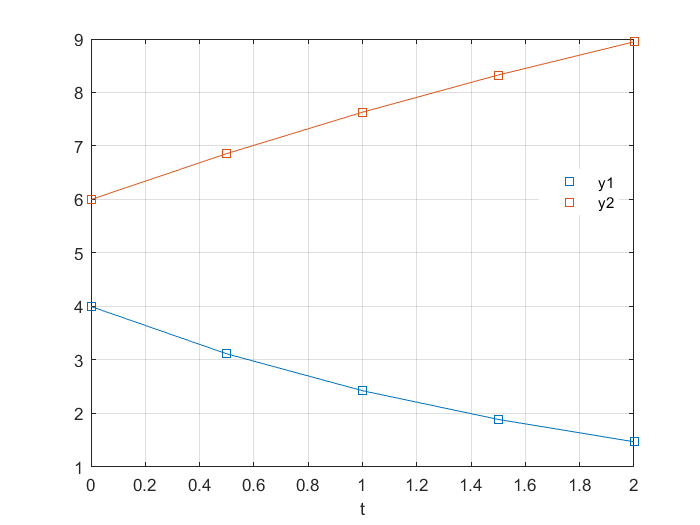

% y1' = -0.5*y1                 y1(0) = 4
% y2' = 4 - 0.3*y2 - 0.1*y1     y2(0) = 6
f = @(t,y) [-0.5*y(1); 4 - 0.3*y(2)- 0.1*y(1)];
y0 = [4;6];
[t,y] = odeRK4(f,y0,0,2,0.5);
[t2,y2] = odeABM4mo(f,y0,0,2,0.5);
plot(t2,y2,'-s');
xlabel('t');
legend('y1','y2','location','best');
grid on;

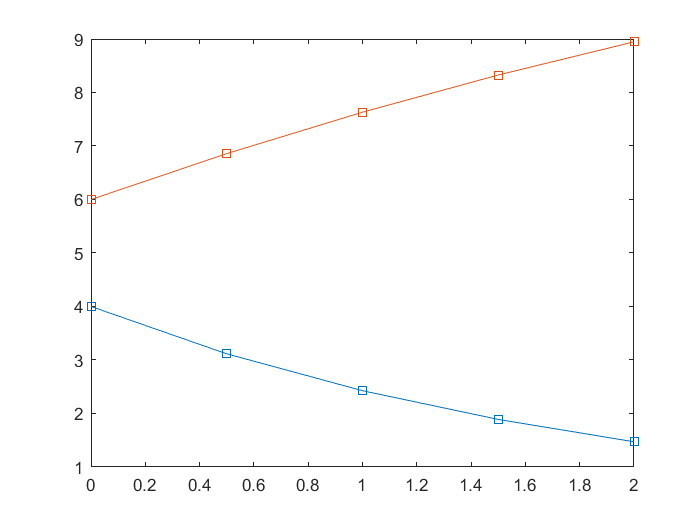

plot(t,y,'-s');

## Sistema de dos ecuaciones lineales **homogeneas** de primer orden

### Matriz M de coeficientes (constantes)

#### Sistema 1

% y' = 3*y-2*z     y(0)=1
% z' = 2*y-2*z     z(0)=-1
syms x1 x2 x1 xp2
x = [x1^2,sqrt(2)*x1*x2,x2^2]

$$x = \left(\begin{array}{ccc} {x_{1}}^{2} & \sqrt{2}\,x_{1}\,x_{2} & {x_{2}}^{2} \end{array}\right)$$

xp = [xp1^2;sqrt(2)*xp1*xp2;xp2^2]

$$xp = \left(\begin{array}{c} {{\mathrm{xp}}_{1}}^{2}\\ \sqrt{2}\,{\mathrm{xp}}_{1}\,{\mathrm{xp}}_{2}\\ {{\mathrm{xp}}_{2}}^{2} \end{array}\right)$$

x*xp

$$ans = {x_{1}}^{2}\,{{\mathrm{xp}}_{1}}^{2}+2\,x_{1}\,x_{2}\,{\mathrm{xp}}_{1}\,{\mathrm{xp}}_{2}+{x_{2}}^{2}\,{{\mathrm{xp}}_{2}}^{2}$$

xv = [x1,x2]

$$xv = \left(\begin{array}{cc} x_{1} & x_{2} \end{array}\right)$$

xpv = [xp1,xp2]

$$xpv = \left(\begin{array}{cc} {\mathrm{xp}}_{1} & {\mathrm{xp}}_{2} \end{array}\right)$$

expand(dot(xv,xpv)*dot(xv,xpv))

$$ans = {{\mathrm{xp}}_{1}}^{2}\,{\bar{x_{1}}}^{2}+2\,{\mathrm{xp}}_{1}\,{\mathrm{xp}}_{2}\,\bar{x_{1}}\,\bar{x_{2}}+{{\mathrm{xp}}_{2}}^{2}\,{\bar{x_{2}}}^{2}$$

#### Sistema 2

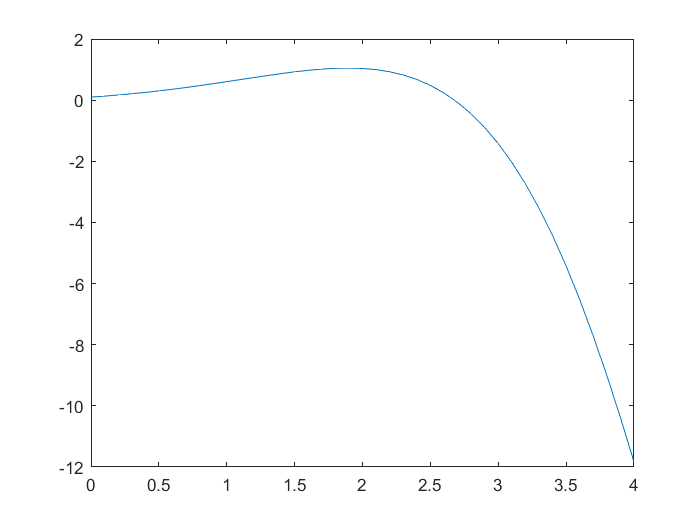

% y' =  y+z     y(0)=0.1
% z' = -y+z     z(0)=0.2
f = @(t,y) [y(1)+y(2);-y(1)+y(2)];
y0 = [0.1;0.2];
[t,y] = odeRK4(f,y0,0,4,0.1);
plot(t,y(1,:))

#### Sistema 3

% y' = -y-6*z    y(0)=0
% z' = 3y+5*z    z(0)=2

#### Sistema 4

% y' = -2*y + 5*exp(-t)
% z' = -(y*z^2)/2;

#### Sistema 5

Pb 25.26 Chapra

Suponga que un proyectil se lanza hacia arriba desde la superficie de la Tierra. Se acepta que la única fuerza que actúa sobre el objeto es la fuerza de la gravedad, hacia abajo. En estas condiciones, se usa un balance de fuerza para obtener,


$$v^{\prime } =-g\frac{R^2 }{{\left(R+y\right)}^2 }$$


donde v = velocidad hacia arriba (m/s), t = tiempo (s), y = altitud (m) medida hacia arriba a partir de la superficie terrestre, g =aceleración gravitacional a la superficie terrestre (≈9.81 m/$s^2$), y R = radio de la tierra (≈6.37 × ${10}^6$ m). Determine la altura máxima que se obtendría si v(t = 0) = 1 400 m/s.

Sistema 5


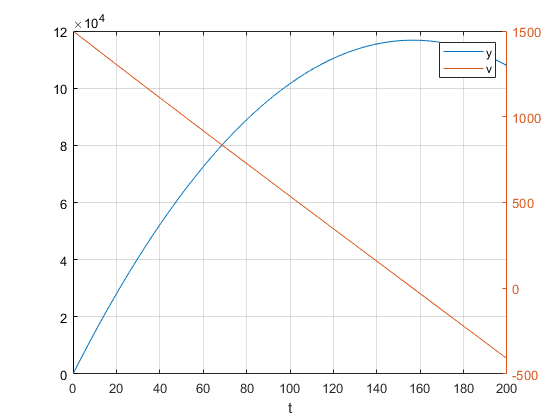

Ymax = 1.1678e+05

Imax = 1568

tMax = 156.7000

% 

## Ecuación diferencial lineal homogenea de segundo orden

Con coeficientes constantes


$$y^{\textrm{''}} +ay^{\prime } +\textrm{by}=0$$


Se convierte a un sistema de dos ecuaciones diferenciales de primer orden definiendo una nueva variable $z=y^{\prime }$


$$\begin{array}{l}
y^{\prime } =z\\
z^{\prime } =y^{\textrm{''}} =-a\;z-b\;y
\end{array}$$



$${\left\lbrack \begin{array}{c}
y\\
z
\end{array}\right\rbrack }^{\prime } =\left\lbrack \begin{array}{cc}
0 & 1\\
-b & -a
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
y\\
z
\end{array}\right\rbrack$$


#### Segundo orden 1

$y^{\prime \prime } +y^{\prime } -2y=0$         $y\left(0\right)=3$, $y^{\prime } \left(0\right)=0$

% 

#### Segundo orden 2

$y^{\prime \prime } -y^{\prime } -2y=0$         $y\left(0\right)=0\ldotp 1$, $y^{\prime } \left(0\right)=0\ldotp 2$

%

#### Segundo orden 3

$y^{\prime \prime } +y^{\prime } -6y=0$         $y\left(0\right)=5$, $y^{\prime } \left(0\right)=0$

% 

#### Segundo orden 4

Harmonic oscillator

$y^{\prime \prime } +y=0$         $y\left(0\right)=4$, $y^{\prime } \left(0\right)=0$

%

#### Segundo orden 5

Motion of a mass connected to a spring, with viscous friction on the surface and an applied external force.

${3y}^{\prime \prime } +{18y}^{\prime } +102y=10$         $y\left(0\right)=0$, $y^{\prime } \left(0\right)=0$

%

#### Segundo orden 6

Resuelve el problema siguiente de t=0 a 5.

$y^{\prime \prime } +{0\ldotp 6y}^{\prime } +8y=0$         $y\left(0\right)=4$, $y^{\prime } \left(0\right)=0$

% 